# Adjust Training Options

Instructions are in the task pane to the left. This activity is ungraded.

Import data set and corresponding labels. Preprocess the data and import it into a cell array.

pathToSignals = "../data/flooddata";
rng default
sigds = signalDatastore(pathToSignals, ...
                        "IncludeSubfolders", true, ...
                        "SignalVariableNames", ["ax" "ay" "az"], ...
                        "ReadOutputOrientation", "row");
labels = folders2labels(pathToSignals);
labels = renamecats(labels, ["0.0 ft" "0.19 ft" "2.5 ft" "4.5 ft"]);
sigt = transform(sigds, @prepsig);
sigdata = readall(sigt);
sigpad = padsequences(sigdata, 2, "Length", 100, "UniformOutput", false);

Split the data set into three sets for training, validation, and testing.

idx = splitlabels(labels, [0.8 0.1]);
traindata = sigpad(idx{1});
trainlabels = labels(idx{1});
valdata = sigpad(idx{2});
vallabels = labels(idx{2});
testdata = sigpad(idx{3});
testlabels = labels(idx{3});

Create layers using the Deep Network Designer. 

layers = [  sequenceInputLayer(3, "Name", "input")
            bilstmLayer(128, "Name", "lstm", "OutputMode", "last")
            dropoutLayer(0.5, "Name", "dropout")
            fullyConnectedLayer(4, "Name", "fc")
            softmaxLayer("Name", "softmax")
            classificationLayer("Name", "classification")];

analyzeNetwork(layers)

**Adjust training options**

Set the sequence length and increase the number of epochs.

opts = trainingOptions( "adam", ...
                        "ValidationData", {valdata vallabels}, ...
                        "Plots", "training-progress", ...
                        "MaxEpochs", 100, ...
                        "MiniBatchSize", numel(trainlabels), ...
                        "Plots", "training-progress");

**Train the network!**

Depending on the number of epochs that you choose, this can take a long time to execute. 

floodnet = trainNetwork(traindata, trainlabels, layers, opts)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       24.29% |       66.67% |       1.3807 |       1.3504 |          0.0010 |
|      50 |          50 |       00:00:10 |       94.92% |       91.67% |       0.1894 |       0.2220 |          0.0010 |
|     100 |         100 |       00:00:12 |       96.61% |      100.00% |       0.1182 |       0.0993 |          0.0010 |
|======================================================================================================================|
Training

floodnet =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'classification'}


Evaluate the network on the testing data. 

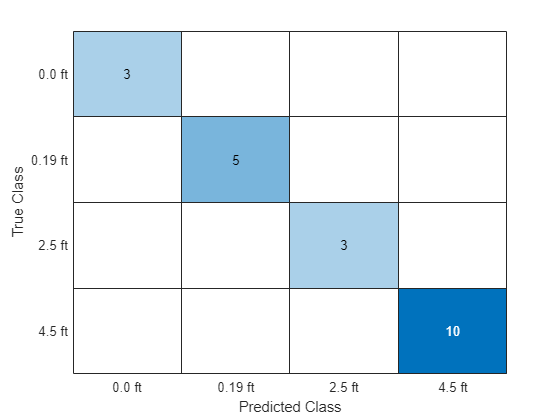

testpred = classify(floodnet, testdata);
confusionchart(testlabels, testpred)

Transformation function for the data set.

function sig = prepsig(sigin)
    sig = cell2mat(sigin);
    sig = sig';
    sig = {sig};
end